## Kalman Filter initialization


dt = lidar_msgs{i}.ScanTime; % Time for each scan
A = [1 0 dt 0;  % state transition model
     0 1 0 dt;
     0 0 1 0;
     0 0 0 1];
H = [1 0 0 0;  % observation model
     0 1 0 0];
% eye(n) is the n-by-n identity matrix 
Q = eye(4) * 0.01; % process noise covariance
R = eye(2) * 0.1; % measurement noise covariance
P = eye(4); % initial estimate of state covariance

x_est = [0.8; 3.0; 0; 0]; % initial state estimate


## Updating filter

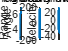


for i = 1:num_msgs
    % Existing code to compute centroids
    centroids(num_scan, 1) = mean(moved_x, 'omitnan');
    centroids(num_scan, 2) = mean(moved_y, 'omitnan');

    % Kalman Filter Prediction
    x_est = A * x_est;
    P = A * P * A' + Q;

    % Kalman Filter Update
    z = [centroids(i, 1); centroids(i, 2)];  % measurement
    y = z - H * x_est;  % measurement residual
    S = H * P * H' + R;  % residual covariance
    K = P * H' / S;  % optimal Kalman gain
    x_est = x_est + K * y;  % updated state estimate
    P = (eye(4) - K * H) * P;  % updated estimate covariance

    % Store filtered centroid
    centroids(i, :) = x_est(1:2)';
end
